state = [200930, -10.04, 7.7204, -7199.5, 5.3356, -5.3356, 0, 0, 0, 0, 0, 0, 0]';
stateCov = diag([1e6, 1e6, 1e6, 1, 1, 1, 100, 100, 100, 1e-4, 1e-4, 1e-4, 1e-4]);
Q = diag([0, 0, 0, 0, 0, 0, 0.02, 0.02, 0.02, 1e-10, 1e-10, 1e-10, 1e-10]);
R = diag([1e-8, 1e-8, 1e-8, 1e-8]);
ekf = trackingEKF(@fx,@hx,state, ...
	'StateCovariance',stateCov, ...
    'StateTransitionJacobianFcn',@Fjac, ...
	'ProcessNoise',Q, ...
    'MeasurementJacobianFcn',@Hjac, ...
	'MeasurementNoise', R);

ukf = trackingUKF(@fx,@hx,state, ...
    'StateCovariance',stateCov, ...
    'ProcessNoise',Q, ...
    'MeasurementNoise',R, ...
    'Alpha',0.1, ...
    'Beta',1, ...
    'Kappa',1);

pf = trackingPF(@fx,@hx,state, ...
    'StateCovariance',stateCov, ...
    'ProcessNoise',Q, ...
    'MeasurementNoise',R);

Perform EKF.

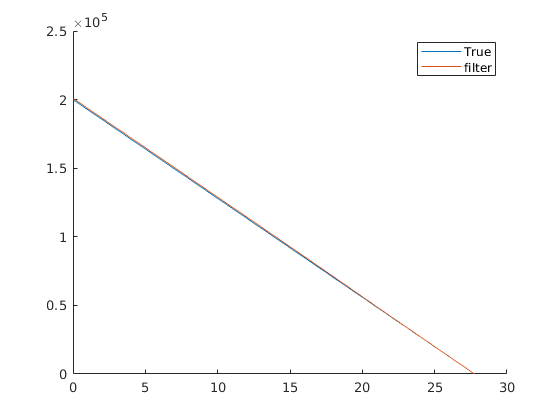

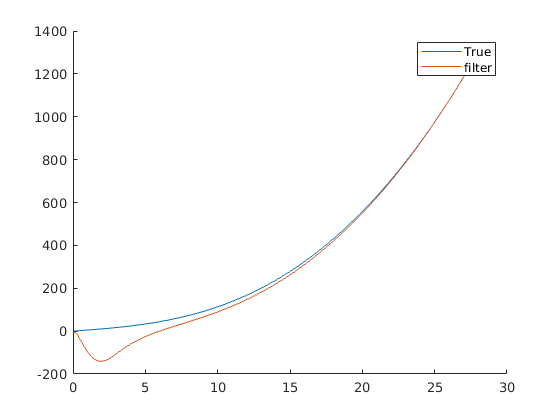

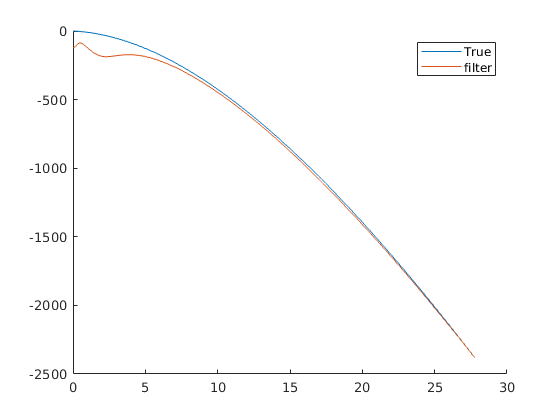

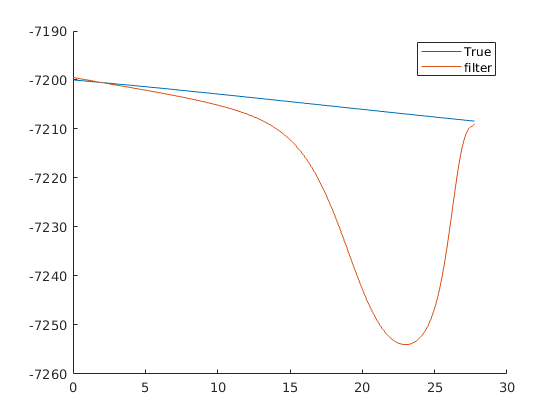

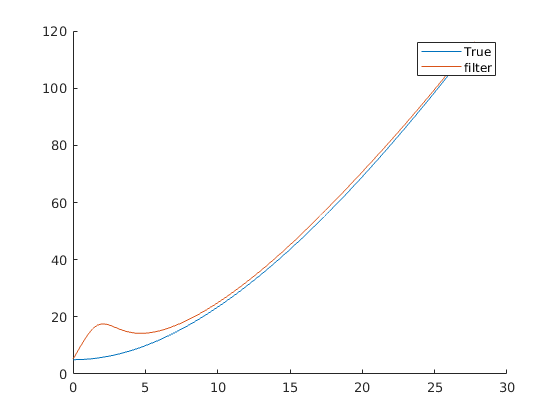

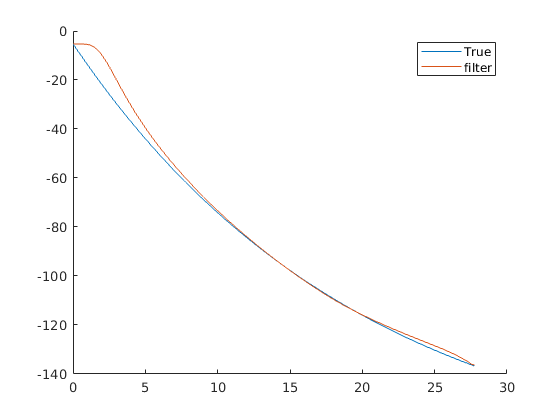

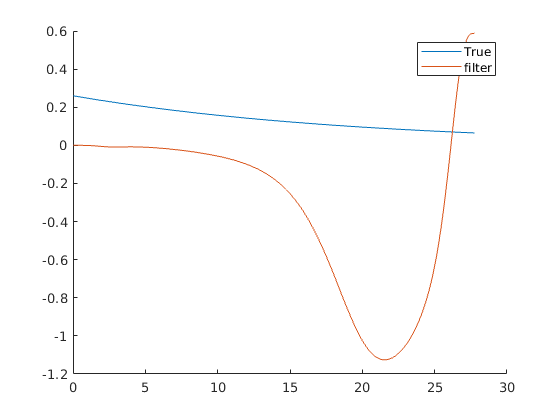

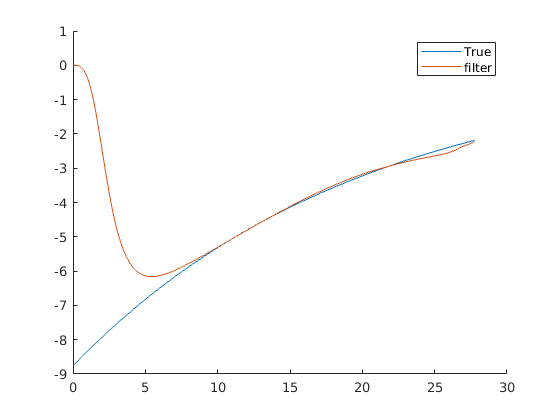

simulation(ekf);

disp('end');

end


Perform UKF.

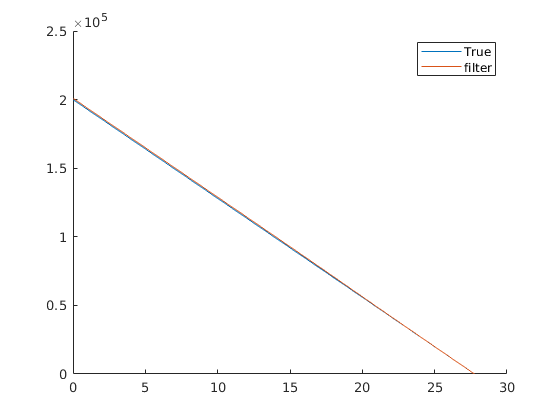

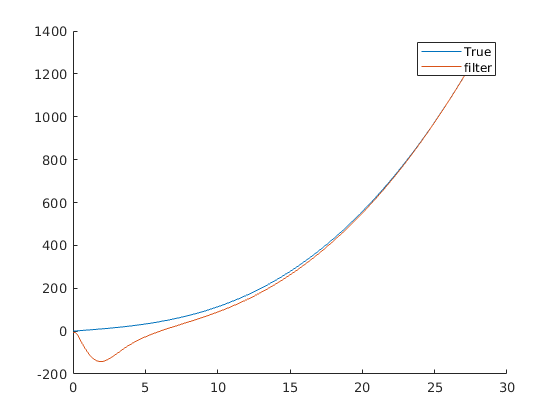

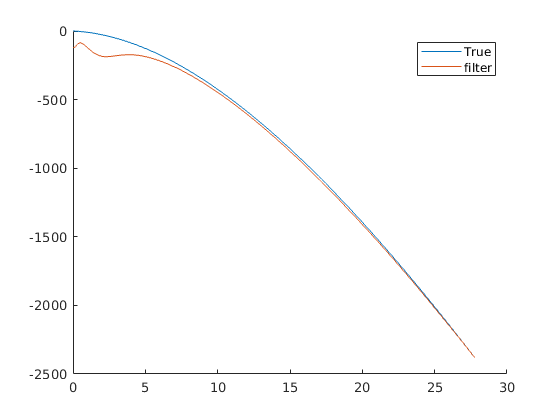

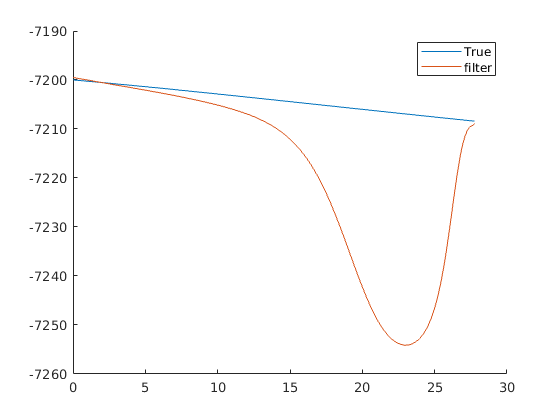

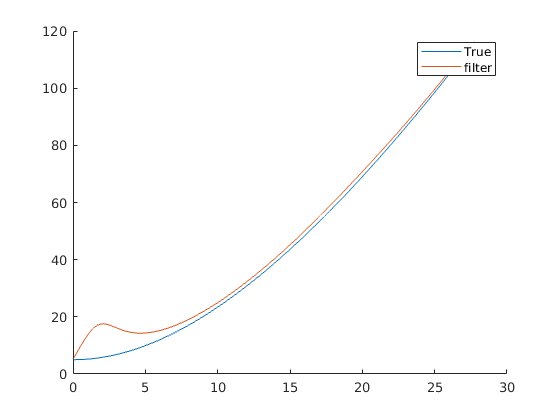

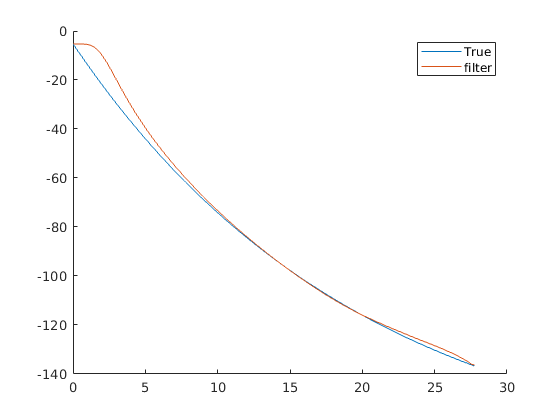

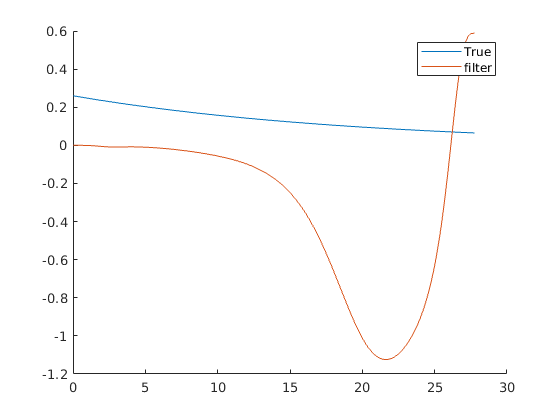

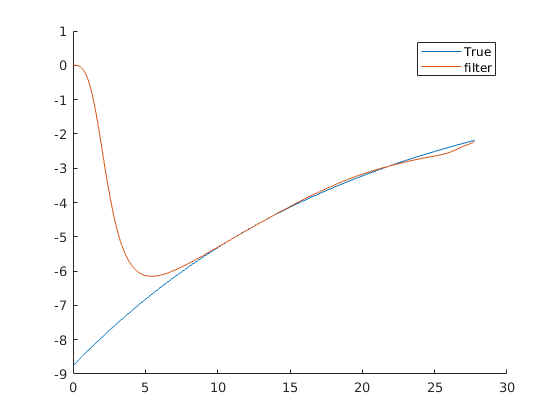

simulation(ukf);

disp('end');

end


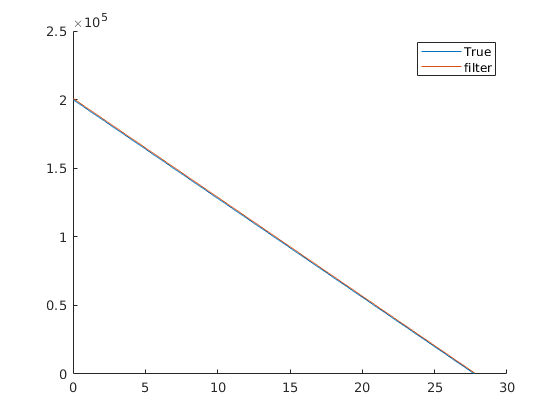

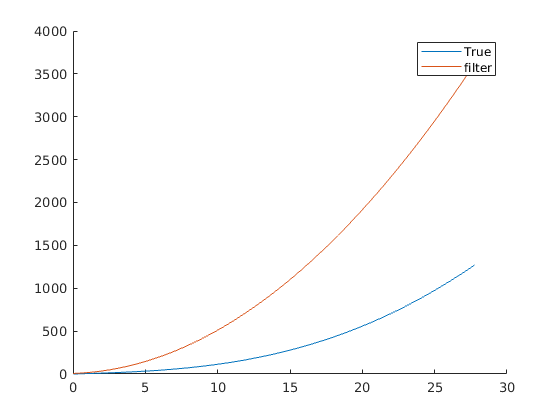

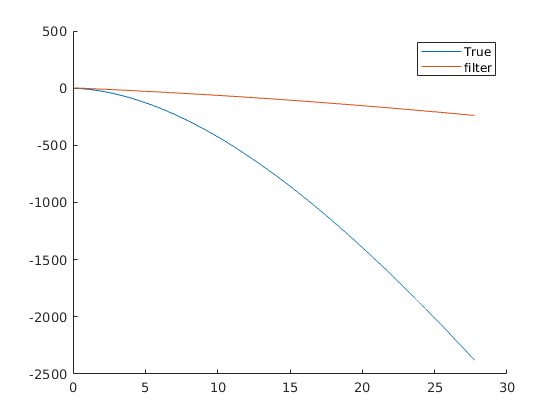

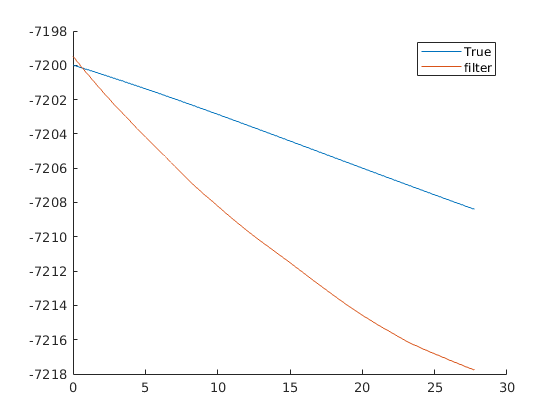

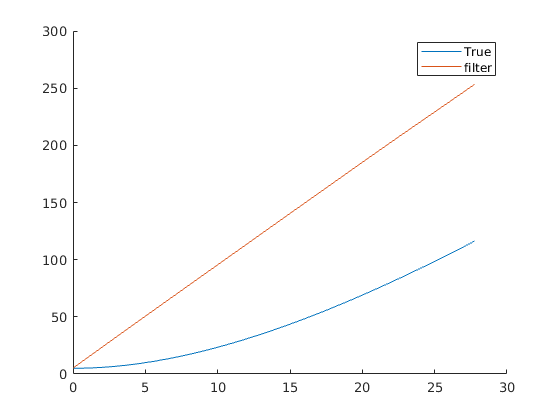

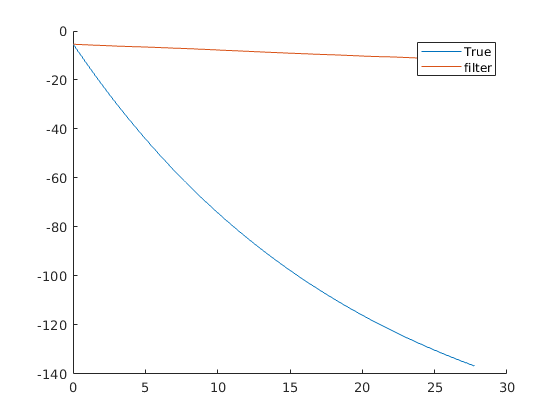

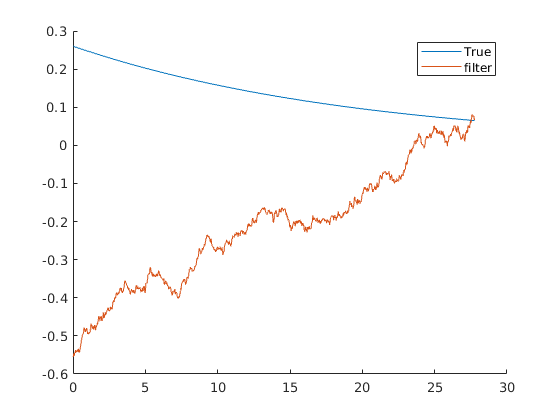

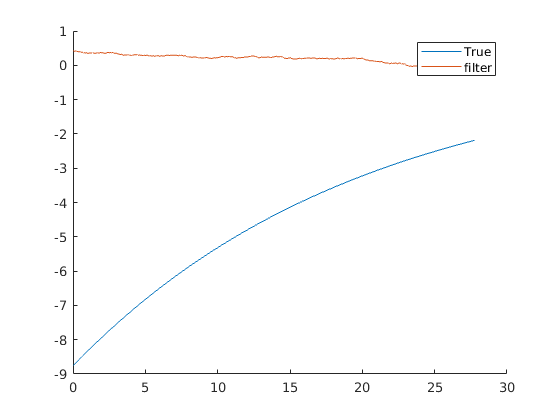

simulation(pf);

function simulation(kf)
dt = 0.02;

load('siml_data.mat');
record_time =0.001;
step = cast(dt/record_time, 'int16');

true_state = [199990, 0, 0, -7200, 5.2, -5.2, 0.2602, -8.7644, -8.7644, 10/60/57.3, -12/60/57.3, -10/60/57.3, 25/60/57.3]';

N = size(BM_acc,2)/step;
xs = zeros(13,N);
track = zeros(13,N);
for i = 1:N
    u = BM_acc(:,(i-1)*step+1);
    
    true_state = fx(true_state, dt, u);
    z = hx(true_state);
    track(:,i) = true_state;
    
    predict(kf, dt, u);
    xs(:,i) = correct(kf, z);
end

N = cast(N, 'double');
time = (1:N)*dt;


for i =1:13
    figure()
    hold on;
    plot(time,track(i,:));
    plot(time, xs(i,:));
    legend('True','filter');
end
end

function F = Fjac(state, varargin)
% F = Fjac(x, dt, sth)
    dt = varargin{1};
    ldx = 0.05;
    ldy = 0.05;
    ldz = 0.05;
    F = diag([1., 1., 1., 1., 1., 1., exp(-ldx*dt), exp(-ldy*dt), exp(-ldz*dt), 1, 1, 1, 1]);
    F(1,4) = dt;
    F(2,5) = dt;
    F(3,6) = dt;
    F(1,7) = 1/ldx^2*(exp(-ldx*dt)+ldx*dt-1);
    F(2,8) = 1/ldy^2*(exp(-ldy*dt)+ldy*dt-1);
    F(3,9) = 1/ldz^2*(exp(-ldz*dt)+ldz*dt-1);
    F(4,7) = 1/ldx*(1-exp(-ldx*dt));
    F(5,8) = 1/ldy*(1-exp(-ldy*dt));
    F(6,9) = 1/ldz*(1-exp(-ldz*dt));
end

function y = fx(x, varargin)
	if nargin == 3
		dt = varargin{1};
		u = varargin{2};
	else
		disp('input for fx is not 3');
	end
		
    B = zeros(13,3);
    B(1,1) = -0.5*dt^2;
    B(2,2) = -0.5*dt^2;
    B(3,3) = -0.5*dt^2;
    B(4,1) = -dt;
    B(5,2) = -dt;
    B(6,3) = -dt;
	y = Fjac(x, varargin{1}) * x + B * u;
end

function H = Hjac(Xe)
    r2 = [0, 500, -500];
    H = zeros(4, 13);
    H(1,1) = -Xe(1)*Xe(2)/(Xe(1)^2+Xe(2)^2+Xe(3)^2)/sqrt(Xe(1)^2+Xe(3)^2);
    H(1,2) = sqrt(Xe(1)^2+Xe(3)^2)/(Xe(1)^2+Xe(2)^2+Xe(3)^2);
    H(1,3) = -Xe(3)*Xe(2)/(Xe(1)^2+Xe(2)^2+Xe(3)^2)/sqrt(Xe(1)^2+Xe(3)^2);
    H(1,10) = 1;

    H(2,1) = Xe(3)/(Xe(1)^2+Xe(3)^2);
    H(2,3) = -Xe(1)/(Xe(1)^2+Xe(3)^2);
    H(2,11) = 1;

    H(3,1) = -(Xe(1)-r2(1))*(Xe(2)-r2(2))/((Xe(1)-r2(1))^2+(Xe(2)-r2(2))^2+(Xe(3)-r2(3))^2)/sqrt((Xe(1)-r2(1))^2+(Xe(3)-r2(3))^2);
    H(3,2) = sqrt((Xe(1)-r2(1))^2+(Xe(3)-r2(3))^2)/((Xe(1)-r2(1))^2+(Xe(2)-r2(2))^2+(Xe(3)-r2(3))^2);
    H(3,3) = -(Xe(3)-r2(3))*(Xe(2)-r2(2))/((Xe(1)-r2(1))^2+(Xe(2)-r2(2))^2+(Xe(3)-r2(3))^2)/sqrt((Xe(1)-r2(1))^2+(Xe(3)-r2(3))^2);
    H(3,12) = 1;

    H(4,1) = (Xe(3)-r2(3))/((Xe(1)-r2(1))^2+(Xe(3)-r2(3))^2);
    H(4,3) = -(Xe(1)-r2(1))/((Xe(1)-r2(1))^2+(Xe(3)-r2(3))^2);
    H(4,13) = 1;
end

function z = hx(x)
    r2 = [0; 500; -500];
    x2 = x(1:3,:)-r2;
    z = [atan(x(2,:)./sqrt(x(1,:).^2 + x(3,:).^2)) + x(10,:);
        -atan(x(3,:)./x(1,:)) + x(11,:);
        atan(x2(2,:)./sqrt(x2(1,:).^2 + x2(3,:).^2)) + x(12,:);
        -atan(x2(3,:)./x2(1,:)) + x(13,:)];
end